# Identify a SINDy model on synthetic Roessler system data

- Lorenz system dynamics: 

                     
$$\begin{array}{l}
\dot{x} =-y-z\\
\dot{y} =x+ay\\
\dot{z} =b+z\left(x-c\right)
\end{array}$$


- Generate noisy data: integrate Roessler system ODE and add Gaussian white noise

- Compute derivatives: using finite difference

- Build library

- Compute sparse regression

- Evaluate performance of SINDy model for forecasting

addpath(genpath(pwd))

## Generate Data

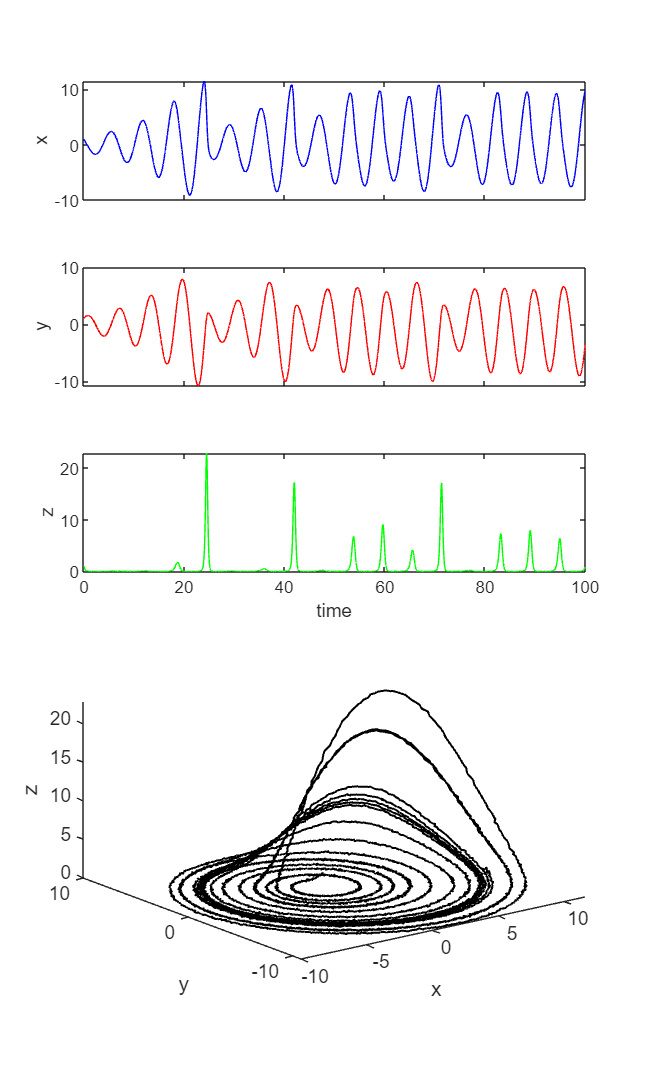

param = [0.2; 0.2; 5.7]; % Lorenz system parameters (chaotic)
n = 3; % number of states
x0 = [1; 1; 1];  % Initial condition
dt = 0.01; % time step
tspan = dt:dt:100; 
options = odeset('RelTol',1e-12,'AbsTol',1e-12*ones(1,3));
[t,x]=ode45(@(t,x) roessler(t,x,param),tspan,x0,options);

% Add Gaussian white noise
rng(1)
sig = 0.01; 
x = x + sig*std(x(:))*randn(size(x)); 

plotRoessler(t,x) % plot data

## Compute Derivative: finite difference

% fourth order central difference
dx = (1/(12*dt))*(-x(5:end,:)+8*x(4:end-1,:)-8*x(2:end-3,:)+x(1:end-4,:)); 

x = x(3:end-2,:); % cut tails
t = t(3:end-2,:);

## Pool Data (i.e., build library of nonlinear time series)

polyorder = 3; % polynomials up to order 3
Theta = poolData(x,n,polyorder);
m = size(Theta,2); % size of library

## Compute Sparse regression: sequential least squares

lambda = 0.01; % lambda is our sparsification knob.
Xi = sparsifyDynamics(Theta,dx,lambda,n); % identify model coefficients
disp(poolDataLIST({'x','y','z'},Xi,n,polyorder)) % display SINDy model

    {0×0 char}    {'xdot'   }    {'ydot'  }    {'zdot'   }
    {'1'     }    {[      0]}    {[     0]}    {[ 0.1996]}
    {'x'     }    {[      0]}    {[0.9999]}    {[      0]}
    {'y'     }    {[-0.9998]}    {[0.2000]}    {[      0]}
    {'z'     }    {[-1.0002]}    {[     0]}    {[-5.6810]}
    {'xx'    }    {[      0]}    {[     0]}    {[      0]}
    {'xy'    }    {[      0]}    {[     0]}    {[      0]}
    {'xz'    }    {[      0]}    {[     0]}    {[ 0.9968]}
    {'yy'    }    {[      0]}    {[     0]}    {[      0]}
    {'yz'    }    {[      0]}    {[     0]}    {[      0]}
    {'zz'    }    {[      0]}    {[     0]}    {[      0]}
    {'xxx'   }    {[      0]}    {[     0]}    {[      0]}
    {'xxy'   }    {[      0]}    {[     0]}    {[      0]}
    {'xxz'   }    {[      0]}    {[     0]}    {[      0]}
    {'xyy'   }    {[      0]}    {[     0]}    {[      0]}
    {'xyz'   }    {[      0]}    {[     0]}    {[      0]}
    {'xzz'   }    {[      0]}    {[     0]}    {[      0

## Use SINDy model for prediction

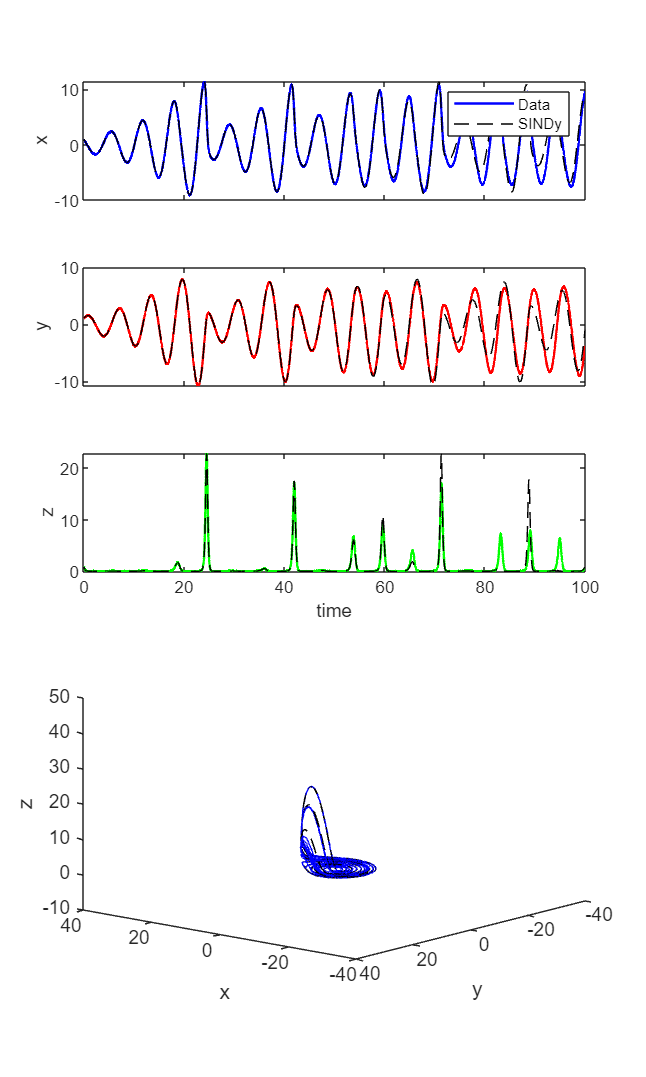

paramSINDy.Xi = Xi;
paramSINDy.polyorder = polyorder;
[tSINDy,xSINDy]=ode45(@(t,x) SINDyODE(t,x,paramSINDy),tspan,x0,options);

plotSINDy(t,x,tSINDy(3:end-2,:),xSINDy(3:end-2,:))